clear; clc; close all;


Input Parameters

Define the input mesh files containing node coordinates and element connectivity

nodesFile = 'nodes_2.txt';        % File containing 3D node coordinates (X, Y, Z)
elementsFile = 'elements_2.txt';  % File containing triangle element definitions


Step 1: Load Mesh Data

Read the triangular mesh from text files. The mesh represents the 3D surface to be machined. Nodes define vertex positions, elements define triangle connectivity.

[nodes, elements] = loadMesh(nodesFile, elementsFile);
% nodes: Nx3 matrix of node coordinates [x, y, z]
% elements: Mx3 matrix of triangle vertex indices


Step 2: Visualize Original 3D Mesh

Display the input 3D surface mesh to verify geometry

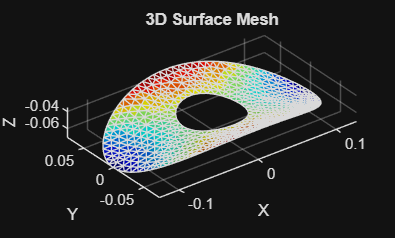

figure('Name', '3D Mesh');
trisurf(elements, nodes(:,1), nodes(:,2), nodes(:,3));  % trisurf: plots triangular surface mesh
axis equal; grid on;  % equal: maintains aspect ratio, grid: shows reference grid
xlabel('X'); ylabel('Y'); zlabel('Z');
title('3D Surface Mesh');
colormap jet;         % jet: color gradient for visualization
lighting gouraud;     % gouraud: smooth shading across triangles
camlight;             % camlight: adds directional lighting for better depth perception

Step 3: Detect Boundary Loops

Identify the outer boundary and any interior holes in the mesh. Boundary edges are those that belong to only one triangle (not shared). Interior nodes are those not on any boundary.

[boundaryLoops, interiorNodes] = findBoundaries(elements, size(nodes,1));
% boundaryLoops: cell array of boundary node indices (each cell is one closed loop)
% interiorNodes: list of node indices that are not on any boundary


Step 4: Visualize Detected Boundaries

Display the mesh with boundaries highlighted to verify correct detection

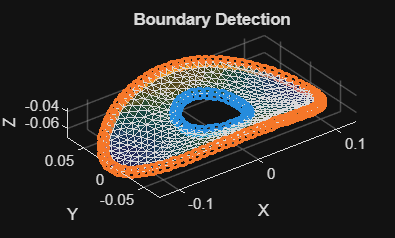

figure('Name', 'Boundary Detection');
trisurf(elements, nodes(:,1), nodes(:,2), nodes(:,3), 'FaceAlpha', 0.3);  % FaceAlpha: transparency
hold on;
colors = lines(length(boundaryLoops));  % lines: generates distinct colors for each loop
for i = 1:length(boundaryLoops)
    boundNodes = nodes(boundaryLoops{i}, :);  % extract coordinates of boundary nodes
    plot3(boundNodes(:,1), boundNodes(:,2), boundNodes(:,3), ...
        'o-', 'Color', colors(i,:), 'LineWidth', 2);  % plot boundary as line with markers
end
axis equal; grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Boundary Detection');

Step 5: Conformal Mapping to 2D Plane

Flatten the 3D surface onto a 2D plane using conformal mapping with free boundary.

This minimizes angle distortion while allowing the boundary shape to adjust freely.

Two random interior nodes are fixed to anchor the mapping and prevent rigid motion.

[uvCoords, ~] = ConformalMapping(nodes, elements, boundaryLoops, interiorNodes);
% uvCoords: Nx2 matrix of 2D coordinates [u, v] corresponding to each 3D node
% The mapping solves a sparse linear system based on cotangent weights (Laplacian)


Step 6: Visualize Flattened 2D Mesh

 Display the result of conformal mapping - the 3D surface flattened to 2D plane

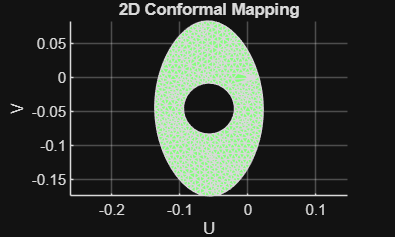

figure('Name', '2D Conformal Mapping');
trisurf(elements, uvCoords(:,1), uvCoords(:,2), zeros(size(uvCoords,1),1));  % plot in 2D (Z=0)
view(2);          % view(2): set camera to top-down view
axis equal; grid on;
xlabel('U'); ylabel('V');
title('2D Conformal Mapping');
colormap jet;

Step 7: Generate 2D Contour-Parallel Toolpaths

Create offset toolpaths in the 2D plane by repeatedly offsetting the boundary inward.

Calculate appropriate offset distance based on UV domain size.

uvRange = [max(uvCoords(:,1)) - min(uvCoords(:,1)), ...
           max(uvCoords(:,2)) - min(uvCoords(:,2))];  % UV domain dimensions
toolpathOffset = mean(uvRange) / 50;  % offset distance (divisor controls toolpath density)
% Larger divisor = more toolpaths = finer spacing

toolpaths2D = generateToolpaths2D(uvCoords, boundaryLoops, toolpathOffset);
% toolpaths2D: cell array where each cell contains a closed 2D toolpath [u, v]
% Uses polybuffer function to offset polygon inward iteratively

Step 8: Visualize 2D Toolpaths

Display the generated toolpaths in the 2D UV plane

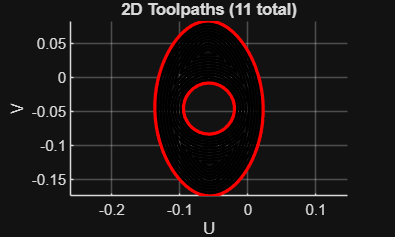

figure('Name', '2D Toolpaths');
hold on; axis equal; grid on;
plot(toolpaths2D{1}(:,1), toolpaths2D{1}(:,2), 'r-', 'LineWidth', 2);  % outer boundary in red
for i = 2:length(toolpaths2D)
    plot(toolpaths2D{i}(:,1), toolpaths2D{i}(:,2), 'k-', 'LineWidth', 1.5);  % interior paths in black
end
xlabel('U'); ylabel('V');
title(sprintf('2D Toolpaths (%d total)', length(toolpaths2D)));

Step 9: Map Toolpaths Back to 3D Surface

Transform the 2D toolpaths back to 3D coordinates on the original surface.

For each 2D point, find which triangle it lies in, compute barycentric coordinates, and interpolate the 3D position from triangle vertices.

toolpaths3D = mapToolpathsTo3D(toolpaths2D, uvCoords, nodes, elements);
% toolpaths3D: cell array where each cell contains a 3D toolpath [x, y, z]


Step 10: Visualize Final 3D Toolpaths

Display the toolpaths on the 3D surface to verify they follow the surface geometry

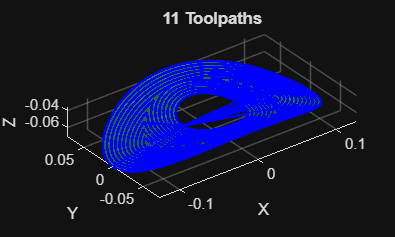

visualizeToolpaths3D(nodes, elements, toolpaths3D);